data=readmatrix('sea_ipf.xlsx')

data =          0         0         0   17.5348  312.6494
         0    0.2500         0   14.9983  254.3634
         0    0.5000         0   12.3125  203.4495
         0    0.7500         0   11.0262  199.2583
         0    1.0000         0   11.5872  200.0000
    0.2500         0         0   16.7012  278.1438
    0.2500    0.2500         0   14.4501  219.2368
    0.2500    0.5000         0   11.5139  167.6756
    0.2500    0.7500         0   10.1731  161.3136
    0.2500    1.0000         0   10.7235  162.6218


n_o=data(:,1)

n_o =          0
         0
         0
         0
         0
    0.2500
    0.2500
    0.2500
    0.2500
    0.2500


n_h=data(:,2)

n_h =          0
    0.2500
    0.5000
    0.7500
    1.0000
         0
    0.2500
    0.5000
    0.7500
    1.0000


x={n_o n_h}

x = 1×2 cell array
    {147×1 double}    {147×1 double}


sea = data(:,4)

sea =    17.5348
   14.9983
   12.3125
   11.0262
   11.5872
   16.7012
   14.4501
   11.5139
   10.1731
   10.7235


ipf = data(:,5)

ipf =   312.6494
  254.3634
  203.4495
  199.2583
  200.0000
  278.1438
  219.2368
  167.6756
  161.3136
  162.6218



input = [n_o n_h];
input0 = input(1:49,:)'

input0 =          0         0         0         0         0    0.2500    0.2500    0.2500    0.2500    0.2500    0.5000    0.5000    0.5000    0.5000    0.5000    0.7500    0.7500    0.7500    0.7500    0.7500    1.0000    1.0000    1.0000    1.0000    1.0000         0         0    0.2500    0.2500    0.5000    0.5000    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.7500    0.7500    0.8750    0.8750    0.8750    0.8750    0.8750    0.8750    0.8750    1.0000    1.0000
         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000    0.6250    0.8750    0.6250    0.8750    0.6250    0.8750         0    0.2500    0.5000    0.6250    0.7500    0.8750    1.0000    0.6250    0.8750         0    0.2500    0.5000    0.6250    0.7500    0.8750    1.0000    0.6250    0.8750


input10 = input(50:98,:)'

input10 =          0         0         0         0         0    0.2500    0.2500    0.2500    0.2500    0.2500    0.5000    0.5000    0.5000    0.5000    0.5000    0.7500    0.7500    0.7500    0.7500    0.7500    1.0000    1.0000    1.0000    1.0000    1.0000         0         0    0.2500    0.2500    0.5000    0.5000    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.7500    0.7500    0.8750    0.8750    0.8750    0.8750    0.8750    0.8750    0.8750    1.0000    1.0000
         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000    0.6250    0.8750    0.6250    0.8750    0.6250    0.8750         0    0.2500    0.5000    0.6250    0.7500    0.8750    1.0000    0.6250    0.8750         0    0.2500    0.5000    0.6250    0.7500    0.8750    1.0000    0.6250    0.8750


input20 = input(99:147,:)'

input20 =          0         0         0         0         0    0.2500    0.2500    0.2500    0.2500    0.2500    0.5000    0.5000    0.5000    0.5000    0.5000    0.7500    0.7500    0.7500    0.7500    0.7500    1.0000    1.0000    1.0000    1.0000    1.0000         0         0    0.2500    0.2500    0.5000    0.5000    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.7500    0.7500    0.8750    0.8750    0.8750    0.8750    0.8750    0.8750    0.8750    1.0000    1.0000
         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000         0    0.2500    0.5000    0.7500    1.0000    0.6250    0.8750    0.6250    0.8750    0.6250    0.8750         0    0.2500    0.5000    0.6250    0.7500    0.8750    1.0000    0.6250    0.8750         0    0.2500    0.5000    0.6250    0.7500    0.8750    1.0000    0.6250    0.8750


target = [sea ipf]

target =    17.5348  312.6494
   14.9983  254.3634
   12.3125  203.4495
   11.0262  199.2583
   11.5872  200.0000
   16.7012  278.1438
   14.4501  219.2368
   11.5139  167.6756
   10.1731  161.3136
   10.7235  162.6218


target0 = target(1:49,:)'

target0 =    17.5348   14.9983   12.3125   11.0262   11.5872   16.7012   14.4501   11.5139   10.1731   10.7235   16.0296   13.5047   10.3229    9.0492    9.5401   16.1166   13.0710    9.7882    8.8773    9.5727   16.8090   13.8279   10.2606    9.4001   10.1379   11.3344   11.3051   10.6106   10.4722    9.3203    9.2256   15.8855   13.2512    9.7928    8.8910    8.6035    8.8293    9.1595    8.8552    9.0782   16.4543   13.4263    9.9694    8.9909    9.0640    9.3117    9.7419    9.2589    9.6812
  312.6494  254.3634  203.4495  199.2583  200.0000  278.1438  219.2368  167.6756  161.3136  162.6218  246.4723  188.7792  139.2802  132.7197  133.6548  236.9103  182.9102  135.6663  125.0000  126.4476  235.6903  184.0271  135.3294  125.5915  127.0000  208.6260  202.2080  161.9050  162.1070  133.4220  133.7410  240.6210  188.0840  135.8240  129.5010  128.0880  127.9510  127.8960  128.0630  125.6210  236.7560  186.0340  135.5340  127.6210  124.8690  126.7430  127.8350  127.3350  127.6640


target10 = target(50:98,:)'

target10 =    16.0491   13.8847   11.2132    9.9227   10.5644   15.5156   13.3197   10.4910    9.2304    9.7960   14.7323   12.2710    9.1609    8.0212    8.5853   14.4785   12.0119    8.7037    7.4170    8.0125   15.2384   12.5978    9.1876    7.9026    8.5514   10.1795   10.2179    9.4896    9.4683    8.2770    8.2877   14.4031   11.9860    8.7135    7.7559    7.4502    7.7224    8.0432    7.6820    7.6643   14.8704   12.3139    8.9303    7.8746    7.6548    7.8924    8.2545    8.1214    8.1785
  216.6630  168.7570  115.7570  106.1700  106.1500  197.1660  144.7100   93.7769   85.0380   85.2365  175.8280  122.4400   76.2829   68.3524   68.3740  168.8340  115.7460   69.6129   62.8834   63.1450  168.9350  116.1190   69.5013   63.2000   63.1000  107.1780  106.2320   84.8153   85.0186   69.1022   68.5144  169.3940  117.0000   70.4053   64.6954   63.6464   63.7061   63.6256   64.1709   63.0683  168.6840  115.9460   69.3267   64.1603   63.2218   62.9843   63.0955   64.1729   62.9479


target20 = target(99:147,:)'

target20 =    14.8271   12.8904   10.4740    9.4232   10.0117   13.6708   11.7863    9.3704    8.4844    8.9954   13.2659   10.9684    8.2072    7.2501    7.8161   13.1122   10.9066    7.9415    6.9468    7.4191   13.8074   11.4919    8.3646    7.3866    8.0064    9.5735    9.6909    8.7248    8.7247    7.4609    7.5269   12.9955   10.8055    7.8696    7.0638    6.9558    7.0605    7.3370    6.9956    7.1137   13.4718   11.2323    8.1773    7.2665    7.1213    7.4117    7.7904    7.4626    7.6494
  234.4620  198.2280  141.7980  122.8030  122.7220  206.7040  159.6250  113.2320   97.6409   97.6388  183.0000  138.5330   86.6921   70.4476   70.6759  167.4960  131.3680   79.5365   64.8147   62.0251  165.2240  129.6320   80.1486   65.3580   62.1317  128.3680  121.9520  101.3330   97.8242   73.7321   70.1971  171.3810  131.3460   78.1264   71.5345   66.1992   63.2150   64.2589   67.6233   62.8610  165.1000  132.7530   79.3773   67.6214   65.4408   64.3203   66.1637   67.5023   64.0137


for n=1:20                    %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB

[net0,tr0] = train(net0,input0,target0);
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input


plot(mse_val0,'-');

disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

     4



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.7835



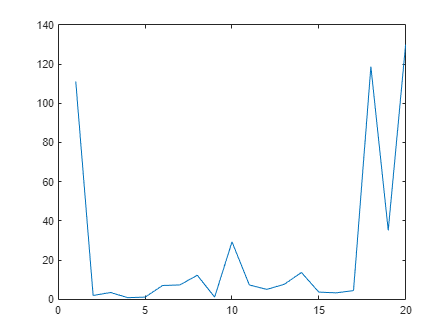

hold off;


output_ANN0 = net0(input0)

output_ANN0 =    17.5298   14.8458   11.8955   11.4385   11.7961   17.7396   14.4805   11.5801   10.3806   10.1317   16.0405   13.5458   10.0932    9.2439    9.2677   15.9011   12.9952    9.7336    8.6685    9.3003   16.7001   13.7927   10.4045    9.4567    9.5770   11.6625   11.4104   10.6969   10.3092    9.6182    9.1578   15.9104   13.2350    9.7619    8.9953    8.6285    8.7826    9.1618    8.8145    9.0940   15.7727   13.1643    9.7131    9.2005    8.9631    9.2485    9.3535    9.6109    9.6169
  312.5729  276.6227  244.0359  201.3091  202.9253  262.9275  223.0783  170.2678  160.6843  164.2973  243.9185  188.9856  139.1978  133.9457  132.8614  232.1040  182.3890  135.8289  127.6815  125.9120  230.2570  183.9912  144.1812  131.2519  128.6307  219.0710  198.4394  161.9386  160.6185  133.0673  133.4104  236.3669  188.1074  135.3839  129.5601  128.7290  129.0971  127.1883  128.7777  126.8507  229.4609  177.2340  135.8122  130.5192  128.2861  127.3053  126.3551  133.9501  130.2842


ANNSEA0 = output_ANN0(1,:)

ANNSEA0 =    17.5298   14.8458   11.8955   11.4385   11.7961   17.7396   14.4805   11.5801   10.3806   10.1317   16.0405   13.5458   10.0932    9.2439    9.2677   15.9011   12.9952    9.7336    8.6685    9.3003   16.7001   13.7927   10.4045    9.4567    9.5770   11.6625   11.4104   10.6969   10.3092    9.6182    9.1578   15.9104   13.2350    9.7619    8.9953    8.6285    8.7826    9.1618    8.8145    9.0940   15.7727   13.1643    9.7131    9.2005    8.9631    9.2485    9.3535    9.6109    9.6169


ANNIPF0 = output_ANN0(2,:)

ANNIPF0 =   312.5729  276.6227  244.0359  201.3091  202.9253  262.9275  223.0783  170.2678  160.6843  164.2973  243.9185  188.9856  139.1978  133.9457  132.8614  232.1040  182.3890  135.8289  127.6815  125.9120  230.2570  183.9912  144.1812  131.2519  128.6307  219.0710  198.4394  161.9386  160.6185  133.0673  133.4104  236.3669  188.1074  135.3839  129.5601  128.7290  129.0971  127.1883  128.7777  126.8507  229.4609  177.2340  135.8122  130.5192  128.2861  127.3053  126.3551  133.9501  130.2842


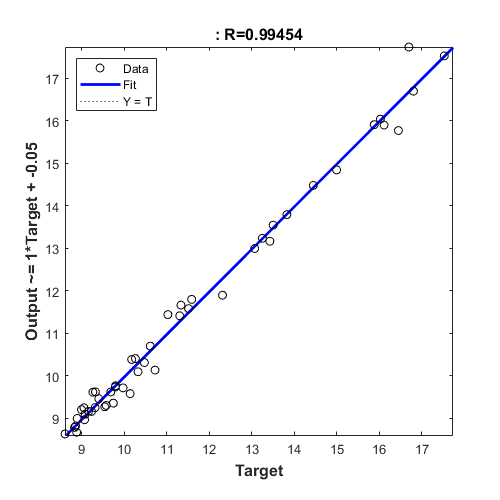

ANNsea0 = sqrt(mean((ANNSEA0' - sea(1:49)).^2));
ANNipf0 = sqrt(mean((ANNIPF0' - ipf(1:49)).^2));
plotregression(sea(1:49),ANNSEA0)

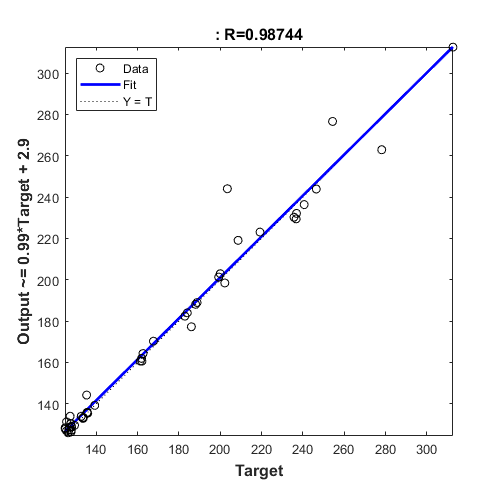

plotregression(ipf(1:49),ANNIPF0)

%for n=1:50                    %number of neuron
net10 = fitnet(6,'trainlm');              %fitnet(hiddenlayersize,training function)
net10.divideParam.trainRatio  = 0.8;
net10.divideParam.valRatio    = 0.2;
net10.divideParam.testRatio   = 0;
net10.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net10.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net10.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net10.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net10.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net10.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net10.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net10.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net10.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
% 
[net10,tr10] = train(net10,input10,target10);
% mse_val10(n)= tr10.best_vperf;
% [M10,I10] = min(mse_val10);        % update the latest minimum mse value (M2) with its index (I2)
% 
% %end
% plot(mse_val10,'-');
% 
% disp('training index of best MSE value set is')
% disp(I10)
% disp('Which has MSE =')
% disp(M10)
% hold off;
% 
% output_ANN10 = net10(input10)
% ANNSEA10 = output_ANN10(1,:)
% ANNIPF10 = output_ANN10(2,:)
% ANNsea10 = sqrt(mean((ANNSEA10' - sea(50:98)).^2));
% ANNipf10 = sqrt(mean((ANNIPF10' - ipf(50:98)).^2));
% plotregression(sea(50:98),ANNSEA10)
% plotregression(ipf(50:98),ANNIPF10)

%for n=1:50                    %number of neuron
net20 = fitnet(9,'trainlm');              %fitnet(hiddenlayersize,training function)
net20.divideParam.trainRatio  = 0.8;
net20.divideParam.valRatio    = 0.2;
net20.divideParam.testRatio   = 0;
net20.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net20.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net20.trainParam.lr           = 0.01;     %Learning rate. The default value is 0.01.
net20.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net20.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net20.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net20.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net20.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net20.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
% 
[net20,tr20] = train(net20,input20,target20);
% mse_val20(n)= tr20.best_vperf;
% [M20,I20] = min(mse_val20);        % update the latest minimum mse value (M2) with its index (I2)

%end
% plot(mse_val20,'-');
% 
% disp('training index of best MSE value set is')
% disp(I20)
% disp('Which has MSE =')
% disp(M20)
% hold off;
% 
% output_ANN20 = net20(input20)
% ANNSEA20 = output_ANN20(1,:)
% ANNIPF20 = output_ANN20(2,:)
% ANNsea20 = sqrt(mean((ANNSEA20' - sea(99:147)).^2));
% ANNipf20 = sqrt(mean((ANNIPF20' - ipf(99:147)).^2));
% plotregression(sea(99:147),ANNSEA20)
% plotregression(ipf(99:147),ANNIPF20)